# Demo for implementing mlinearize in Simulink model using s-function block

This demo shows the multilinearization of the essential system from DemoSSA.mlx. The nonlinear part of the grid-following converter (GFL) is multilinearized with the function mlinearize to create an mss object, which is taken into the Simulink model with the help of s-function block.

clear;
clc;

Load nonlinear model to multilinearize

model = "nonlinearGFLcontrol_shell";

Get parameters and inputs for the nonlinear part from the nonlinear GFL reference model. The values of the bounds of operating region for states, inputs, and outputs are obtained from the nonlinear simulation. If they are known to the users, these values can be entered or loaded without running the nonlinear model.

% run nonlinear GFL reference model
% from DemoSSA2bus.mlx
SimulationSetup.model='GFM_GFL'; % 'GFL','GFM','GFM_GFL'
SimulationSetup.JacobianCalculation='no'; % 'yes','no'
SimulationSetup.caseStudy='VoltageStep_SCR5_XR10_equalLoadDistribution_Rstep055'; % check selectionCaseStudy
SimulationSetup.Plotting.savePlots='no'; % Choose between 'yes' and 'no' 
SimulationSetup.Solver.MaxStep=1e-4;
SimulationSetup.Solver.RelTol=1e-4;
SimulationSetup.Solver.MTI='dmsim'; % 'dmsim'
SimulationSetup.Descriptor.Status='no'; % 'on'
SimulationSetup.Descriptor.savePlots='no'; %'yes', 'no'
SimulationSetup.Descriptor.SimulationTime=0.01;%0.01;
SimulationSetup.totalNumberOfSimulationScenarios=1;
SimulationSetup.eigenvalueAnalysis='no';% 'single', 'trajectory'
SimulationSetup.ModelABCcoordinates.simulate='no'; 
SimulationSetup.ComputationalAssessment='no';

parametrization
selectionCaseStudy

nl_refmod = sim("GFM_GFL_referenceModel_nonlinear.slx");
nl_refmod.network.Data=squeeze(nl_refmod.network.Data).';
v_pcc_DQ = nl_refmod.network.Data(:,5:6);
angle_Grid = nl_refmod.angles.signals.values(:,1);
iDQ_Conv2 = nl_refmod.network.Data(:,9:10);
idqref_Conv2_dq = nl_refmod.converter2.signals.values(:,14:15);
u = [v_pcc_DQ angle_Grid iDQ_Conv2 idqref_Conv2_dq];

% run simulation of nonlinear part to get estimates for bounds
t=nl_refmod.tout;
tsim = t(end);
nonlinshellsim = sim(model);

% get values for bounds
xout=nl_refmod.xout;

converter2thetaPLL = xout{3}.Values.Data;
converter2xldCC = xout{5}.Values.Data;
converter2xlPLL = xout{2}.Values.Data;
converter2xlqCC = xout{6}.Values.Data;

yout = [];
for l = 1:numElements(nonlinshellsim.yout)
    yout = [yout squeeze(nonlinshellsim.yout{l}.Values.Data)];
end

% get bounds min max of states/inputs/outputs
% dimension of the bounds should be n+m+p (number of states + number of
% inputs + number of output)
up_bnd = [max(converter2thetaPLL) max(converter2xldCC) max(converter2xlPLL) max(converter2xlqCC) max(u) max(yout)];
low_bnd = [min(converter2thetaPLL) min(converter2xldCC) min(converter2xlPLL) min(converter2xlqCC) min(u) min(yout)];

Do multilinearization with mlinearize:

% set up grid - Smolyak grid
level = 4;
max_order = 3;

% do mlinearize
mltic=tic;
msys = mss.mlinearize(model, low_bnd, up_bnd, level, max_order);

Order of states taken by  Simulink:
    {'nonlinearGFLcontrol_shell/PLL/Integrator1'       }
    {'nonlinearGFLcontrol_shell/Subsystem3/Integrator' }
    {'nonlinearGFLcontrol_shell/PLL/Integrator'        }
    {'nonlinearGFLcontrol_shell/Subsystem3/Integrator1'}



mltoc=toc(mltic);
fprintf('%.2f sec - Multilinearisation\n', mltoc);

5.96 sec - Multilinearisation


Simulink simulation with mss object in s-function block

% set initial states from extracted x at a certain time point where the
% system is stable. Can also start from default initial states or initial
% states of the user's choice.

idxTinit = find(t>=0.1); % to set simulation time in Simulink, use Model Settings
idxTinit = idxTinit(1);
idxTend = find(t<=1);
idxTend = idxTend(end);

xinit.Values = [];
xinit.stateName = strings(0,1);
m=1;
for l=1:numElements(xout)
    if contains(xout{l}.Name, 'DSTATE')
        l = l+1;
    else
    xinit.Values = [xinit.Values xout{l}.Values.Data(idxTinit,:)];
    xinit.stateName(end+1) = xout{l}.Name;
    if length(xout{l}.Values.Data(2,:))==2
        xinit.stateName(end+1) = xout{l}.Name;
    end
    end
end

x0 = [xinit.Values(3) xinit.Values(5) xinit.Values(2) xinit.Values(6)]; % for the s-function block
xInitial = [xinit.Values x0]; % for the whole referenceModel

% run sim with s-function
mlinsim = sim("GFM_GFL_referenceModel_mss_sfunc");

Model 'GFM_GFL_referenceModel_mss_sfunc' was exported from R2024b to R2023b. To find blocks that were removed during the export operation, click here. Save the model to remove this notification.


The comparison of the simulation of the multilinearized model and the nonlinear model can be shown in the scope

## Compare results with MTI simulation

opt=odeset('MaxStep',1e-4);
dmsys=dmss(msys);

Reduced by 2048 column(s) and 0 equation(s) with trivial Reduction due to duplications.



tsig = t(idxTinit:idxTend);
usig = u(idxTinit:idxTend,:);
simout=dmsim(dmsys,x0,[],[],tsig,usig,opt);

## Plot results

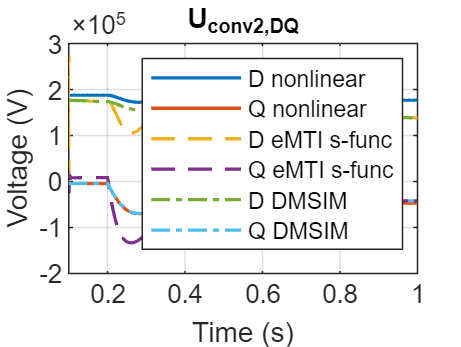

figure
plot(nl_refmod.converter2_UDQ.Time, nl_refmod.converter2_UDQ.Data,'LineWidth',1.1)

hold on
plot(mlinsim.tout, mlinsim.eMTIUDQ.Data,'--','LineWidth',1.1)
hold on
plot(simout.tsim,simout.y(:,3:4),'-.','LineWidth',1.1)
xlim([mlinsim.tout(1) mlinsim.tout(end)])
title('U_{conv2,DQ}')
ylabel('Voltage (V)')
xlabel('Time (s)')
grid on
box on
legend('D nonlinear', 'Q nonlinear','D eMTI s-func', 'Q eMTI s-func',  'D DMSIM', 'Q DMSIM')